# Actividad 1 (Mapeo de coordenadas)

Ana Itzel Hernández García A01737526

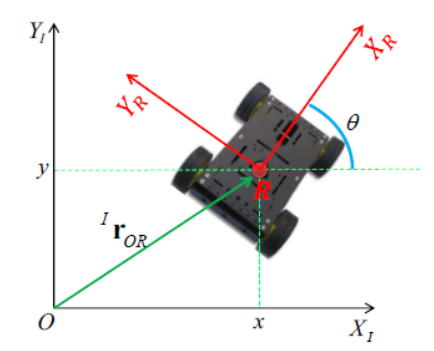

**Obtener** el mapeo de las siguientes coordenadas inerciales, hacia un marco de referencia local y comprobar si se obtienen las coordenadas iniciales con el mapeo inverso

En este código se definen y procesan las coordenadas inerciales en un tiempo inicial (tiempo 1)

% Limpieza de pantalla
clear all
close all
clc

tic
%Insisos
ins = ['a', 'b', 'c', 'd', 'e', 'f', 'g', 'h', 'i', 'j', 'k', 'l', 'm', 'n','ñ', 'o', 'p', 'q', 'r', 's',];

### Coordenadas inerciales 

a) **(-5, 9, -2°)**               b) **(-3, 8, 63°)**                  c) **(5, -2, 90°)**                 d) **(0, 0, 180°)**

e) **(-6, 3, -55°)**             f) **(10, -2, 45°) **                 g) **(9, 1, 88°)**                  h) **(5, 2, 33°)**

i) **(-1, -1, 21°)**               j) **(6, 4, -40°) **                  k) **(5, 7, 72°)**                   l) **(7, 7,**  **30°)**

m) **(11, -4, 360°)**          n) **(20, 5, 270°) **               ñ) **(10, 9, 345°)**               o) **(-9, -8, 8°)**

p) **(1, 1, 60°)**                q) **(3, 1, -30°) **                  r) **(15, 2, 199°)**                s) **(-10, 0, 300°)**

Definición de los vectores con las coordenadas inerciales (del sistema inercial/global) para un tiempo 1

% Posición inicial eje x
x_vect = [-5, -3, 5, 0,-6, 10, 9, 5,-1, 6, 5, 7, 11, 20, 10, -9, 1, 3, 15, -10];
 % Posición inicial eje y
y_vect = [9, 8, -2, 0, 3, -2, 1, 2, -1, 4, 7, 7, -4, 5, 9, -8, 1, 1, 2, 0];
% Orientación inicial del robot
th_vect = [-2, 63, 90, 180, -55, 45, 88, 33, 21, -40, 72, 30, 360, 270, 345, 8, 60, -30, 199, 300];

Mediante un ciclo `for` que recorre cada uno de los 20 robots: 

Se obtiene la posición inicial `(x1, y1)` y la orientación inicial `th1` (convertida a radianes con `deg2rad`) para el robot actual. El vector de posición `Pos_1`, representa la posición inicial del robot en coordenadas inerciales.La matriz de rotación `Rot_1` a partir del ángulo `th1 `representa cómo rotar del sistema inercial al sistema local del robot.Se calcula el vector `xi_local_1` mediante la multiplicación de la matriz de rotación por el vector de posición. Esto representa la posición del robot expresada en su sistema local. La magnitud del vector `xi_local_1` para conocer la distancia desde el origen del sistema local. Como comprobación, se calcula la matriz inversa de rotación `inv_Rot_1` y se multiplica por `xi_local_1` para regresar al vector de posición inercial (`xi_inercial_1`). Este paso sirve para verificar que la transformación es reversible y correcta.

for i = 1:20
    x1 = x_vect(i);
    y1 = y_vect(i);
    th1 = deg2rad(th_vect(i));
    letra = ins(i);

    sprintf('Sistema %s', letra)
    sprintf('(%d,%d, %.2f°)', x1, y1,th1)

    % Definición del vector de posición y matriz de rotación para un tiempo 1
    Pos_1 = [x1;
             y1;
             0];
    Rot_1 = [cos(th1)   -sin(th1)   0;
             sin(th1)    cos(th1)   0;
             0           0          1];
    
    % Transformación dle marco de referencia inercial al local
    xi_local_1 = Rot_1 * Pos_1
    % Magnitud del vector resultante
    magnitud = sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)
    % Devolución del vector inercial (Comprobación)
    inv_Rot_1 = inv(Rot_1);

    
    xi_inercial_1 = inv_Rot_1 * xi_local_1
end 

ans = 'Sistema a'

ans = '(-5,9, -0.03°)'

xi_local_1 =    -4.6829
    9.1690
         0


magnitud = 10.2956

xi_inercial_1 =    -5.0000
    9.0000
         0


ans = 'Sistema b'

ans = '(-3,8, 1.10°)'

xi_local_1 =    -8.4900
    0.9589
         0


magnitud = 8.5440

xi_inercial_1 =     -3
     8
     0


ans = 'Sistema c'

ans = '(5,-2, 1.57°)'

xi_local_1 =     2.0000
    5.0000
         0


magnitud = 5.3852

xi_inercial_1 =      5
    -2
     0


ans = 'Sistema d'

ans = '(0,0, 3.14°)'

xi_local_1 =      0
     0
     0


magnitud = 0

xi_inercial_1 =      0
     0
     0


ans = 'Sistema e'

ans = '(-6,3, -0.96°)'

xi_local_1 =    -0.9840
    6.6356
         0


magnitud = 6.7082

xi_inercial_1 =    -6.0000
    3.0000
         0


ans = 'Sistema f'

ans = '(10,-2, 0.79°)'

xi_local_1 =     8.4853
    5.6569
         0


magnitud = 10.1980

xi_inercial_1 =     10
    -2
     0


ans = 'Sistema g'

ans = '(9,1, 1.54°)'

xi_local_1 =    -0.6853
    9.0294
         0


magnitud = 9.0554

xi_inercial_1 =      9
     1
     0


ans = 'Sistema h'

ans = '(5,2, 0.58°)'

xi_local_1 =     3.1041
    4.4005
         0


magnitud = 5.3852

xi_inercial_1 =      5
     2
     0


ans = 'Sistema i'

ans = '(-1,-1, 0.37°)'

xi_local_1 =    -0.5752
   -1.2919
         0


magnitud = 1.4142

xi_inercial_1 =    -1.0000
   -1.0000
         0


ans = 'Sistema j'

ans = '(6,4, -0.70°)'

xi_local_1 =     7.1674
   -0.7925
         0


magnitud = 7.2111

xi_inercial_1 =     6.0000
    4.0000
         0


ans = 'Sistema k'

ans = '(5,7, 1.26°)'

xi_local_1 =    -5.1123
    6.9184
         0


magnitud = 8.6023

xi_inercial_1 =      5
     7
     0


ans = 'Sistema l'

ans = '(7,7, 0.52°)'

xi_local_1 =     2.5622
    9.5622
         0


magnitud = 9.8995

xi_inercial_1 =     7.0000
    7.0000
         0


ans = 'Sistema m'

ans = '(11,-4, 6.28°)'

xi_local_1 =    11.0000
   -4.0000
         0


magnitud = 11.7047

xi_inercial_1 =     11
    -4
     0


ans = 'Sistema n'

ans = '(20,5, 4.71°)'

xi_local_1 =     5.0000
  -20.0000
         0


magnitud = 20.6155

xi_inercial_1 =     20
     5
     0


ans = 'Sistema ñ'

ans = '(10,9, 6.02°)'

xi_local_1 =    11.9886
    6.1051
         0


magnitud = 13.4536

xi_inercial_1 =    10.0000
    9.0000
         0


ans = 'Sistema o'

ans = '(-9,-8, 0.14°)'

xi_local_1 =    -7.7990
   -9.1747
         0


magnitud = 12.0416

xi_inercial_1 =    -9.0000
   -8.0000
         0


ans = 'Sistema p'

ans = '(1,1, 1.05°)'

xi_local_1 =    -0.3660
    1.3660
         0


magnitud = 1.4142

xi_inercial_1 =     1.0000
    1.0000
         0


ans = 'Sistema q'

ans = '(3,1, -0.52°)'

xi_local_1 =     3.0981
   -0.6340
         0


magnitud = 3.1623

xi_inercial_1 =     3.0000
    1.0000
         0


ans = 'Sistema r'

ans = '(15,2, 3.47°)'

xi_local_1 =   -13.5316
   -6.7746
         0


magnitud = 15.1327

xi_inercial_1 =    15.0000
    2.0000
         0


ans = 'Sistema s'

ans = '(-10,0, 5.24°)'

xi_local_1 =    -5.0000
    8.6603
         0


magnitud = 10

xi_inercial_1 =   -10.0000
    0.0000
         0


toc

Elapsed time is 0.434673 seconds.
